#### **Here we see the filter bank as designed by** ***C. Li, C. Zheng, and C. Tai, “Detection of ECG characteristic points using wavelet transforms,” IEEE Trans. Biomed. Eng., vol. 42, pp. 21–28, Jan. 1995"***

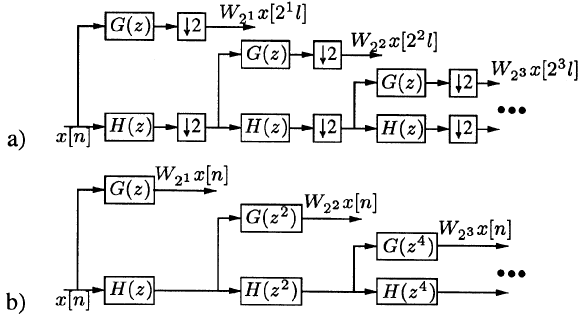

Two filter-bank implementations: a) Mallat's algorithm  b) Algorithm a trous.

Ofcourse we will utilize algorithm a trous

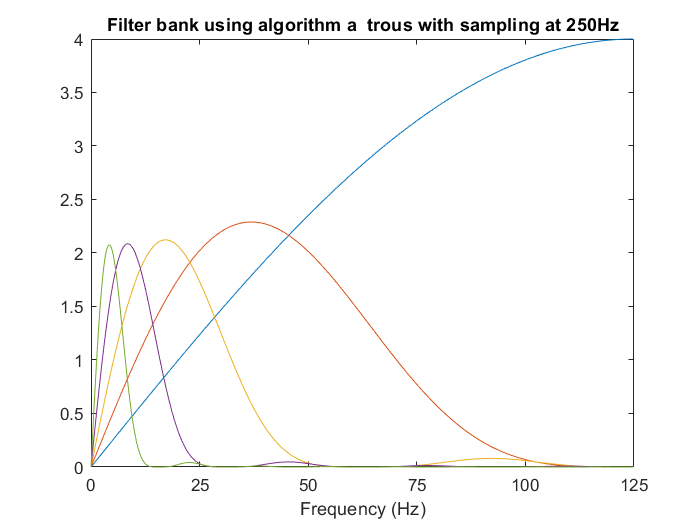

fs = 250;
Gz = 2*[1 -1];
Hz = 1/8*[1 3 3 1];
level = 5;
G = {};
H = {};
G{1} = [Gz];
H{1} = [Hz];
for i = 1:level
    G{i+1} = upsample(Gz,2^i) ;
    H{i+1} = upsample(Hz,2^i) ; 
end

W{1} = G{1};
for i = 2:level
    temp = G{i};
    for j = 1:(i-1)
        temp = conv(temp , H{j});
    end
    W{i} = [temp];
end

for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*125/pi;
    plot(q,abs(h));
    hold on
end
title 'Filter bank using algorithm a  trous with sampling at 250Hz'
xlabel 'Frequency (Hz)'
xlim([0,125])
xticks([0,25,50,75,100,125])

Now, we resample the impulse responses to obtain equivalent response at 360Hz:

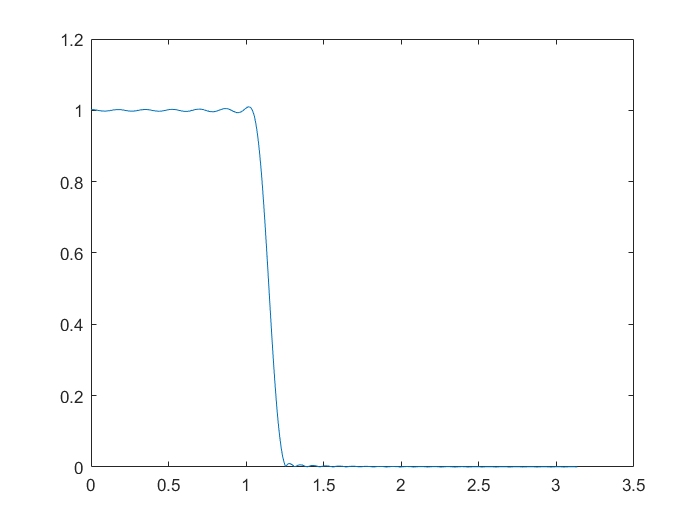

figure
fsamp=pi;
fcuts=[pi/6+0.0,pi/6+0.1];
mags=[1,0];
devs=[0.05,0.01];
[n,Wn,beta,ftype] = kaiserord(fcuts,mags,devs,fsamp);
hh = fir1(n,Wn,ftype,kaiser(n+1,beta),'noscale');
for i = 1:(level)
    W{i}=2*upsample(W{i},3);
    W{i}=conv(W{i},hh);
    W{i}=downsample(W{i},2);
end
    [h,q] = freqz( hh ,[1]);
    plot(q,abs(h))

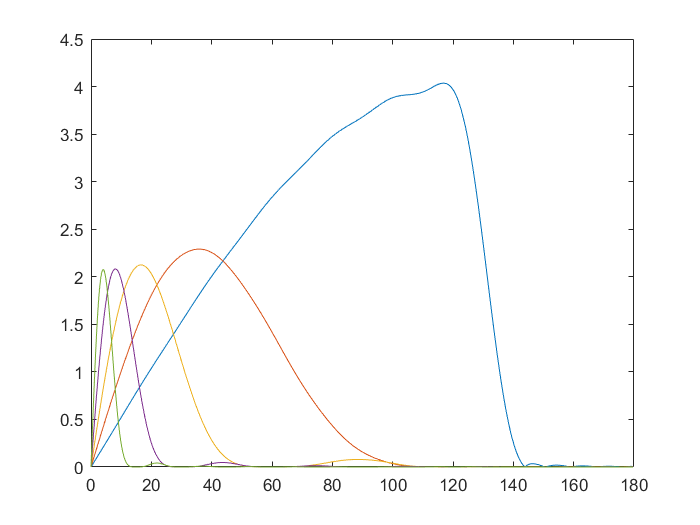

    figure

for i = 1:(level)
    [h,q] = freqz( W{i} ,[1]);
    q = q*180/pi;
    plot(q,abs(h));
    hold on
end

load('sig.mat')
load('tm.mat')
tm=tm{1}

tm = 	1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


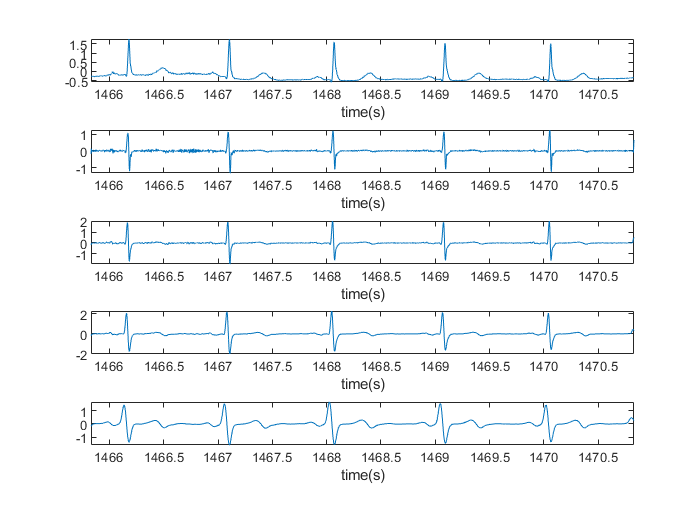

sig=sig{1};
x=sig(33000:34000);
x=sig(527700:529500);    %baseline wandering
tm=tm(527700:529500);
figure
w1=conv(x,W{1},'same');
w2=conv(x,W{2},'same');
w3=conv(x,W{3},'same');
w4=conv(x,W{4},'same');
w5=conv(x,W{5},'same');
figure()
subplot(5,1,1)
plot(tm,x)
axis tight
xlabel 'time(s)'
subplot(5,1,2)
plot(tm,w1)
xlabel 'time(s)'
axis tight
subplot(5,1,3)
plot(tm,w2)
xlabel 'time(s)'
axis tight
subplot(5,1,4)
plot(tm,w3)
axis tight
xlabel 'time(s)'
subplot(5,1,5)
plot(tm,w4)
axis tight
xlabel 'time(s)'

Now we move to peak detection

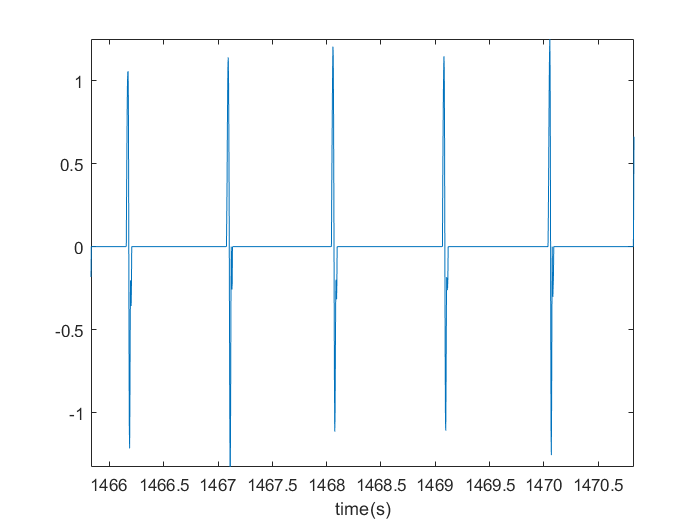

e_1_QRS=rms(w1);
e_2_QRS=rms(w2);
e_3_QRS=rms(w3);
e_4=0.5*rms(w4);
peaks=w1.*(abs(w1)>e_1_QRS);
figure
plot(tm,peaks)
axis tight
xlabel 'time(s)'

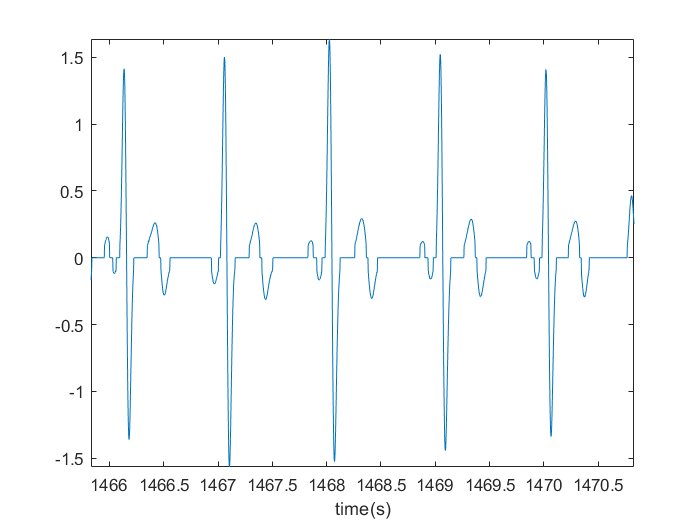

e_T=0.25*rms(w4);
e_P=0.02*rms(w4);
peaks=w4.*(abs(w4)>e_T);
figure
plot(tm,peaks)
axis tight
xlabel 'time(s)'